# Blind deconvolution using MATLAB

## *Bjorn Saltzmann*

## Using `deconvblind`

This document details the insights gained from experimenting with applying blind deconvolution methods to ARPES data in MATLAB. For additional information see the function documentation at [mathworks.com/help/images/ref/deconvblind.html](https://ch.mathworks.com/help/images/ref/deconvblind.html) as well as the usage example at [mathworks.com/help/images/deblur-with-the-blind-deconvolution-algorithm.html](https://ch.mathworks.com/help/images/deblur-with-the-blind-deconvolution-algorithm.html).

[Angle,Energy,Scan,Data,ep,Note]=ReadARPES('014_FS.h5');

- Reading in data


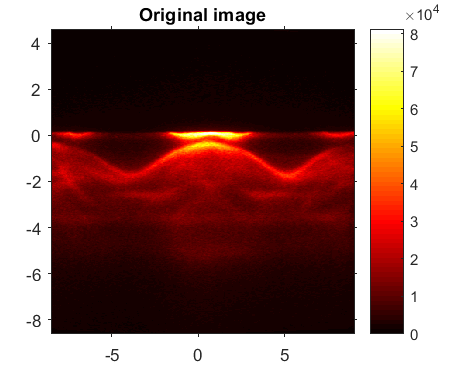

nFrame=10; Img=Data(:,:,nFrame);
ImData(Angle,Energy,Img);
colormap hot; set(gca,'TickDir','Out');
title('Original image');colorbar;set(gcf,'Position',[0,0,380,300])

The MATLAB function used for the blind deconvolution is `deconvblind` which has the following syntax:

% [J,psfr] = deconvblind(I,psfi,iter,dampar,weight,readout)

where `I` is the initial image, `psfi` the first guess at the point-spread function (PSF), `iter` the number of iteration, `dampar` a damping threshold, `weight` a weighting factor for individual pixels and `readout` a description of the camera noise of the image.

We set these variables as follows:

PSFsize=[ceil(size(Img,1)/100)*2,ceil(size(Img,2)/100)*2];
psfi=ones(PSFsize);

iter=5;
dampar=0;

Weight=ones(size(Img));
Weight(Img<max(Img(:))*0.025)=0;
Weight=flipud(Weight);

As stated in the documentation of `deconvblind,` the values of the initial PSF guess are much less relevant than its size and starting from a matrix of all ones yields perfectly reasonable results.

The size used here, based on the total size, in pixels, of the image, is solely based on experience of it yielding good results for data analysed so far.

The low number of iterations is inspired by the findings of Rameau *et al.* `[J. Rameau, H. Yango, P.Johnson (2010); Application of the Lucy–Richardson deconvolution procedure to high resolution photoemission spectra. Journal of Electron Spectroscopy and Related Phenomena. 181.35.10.1016/j.elspec.2010.05.025.]` for the Lucy-Richardson algorithm which is also used by `deconvblind.` They found that the reconstruction quality for ARPES data only improves marginally for more iterations of the algorithm beyond four to five.

The damping is left at the default of no damping as it didn't provide any visible improvements to the results and would sometimes damp out all changes.

The weight of pixels with an intensity below 2.5% of the global maximum intensity is set to 0 to avoid noise measured e.g. above the Fermi level affecting the results. In effect, this sets a threshold intensity value for a pixel to be considered in the algorithm. This setting mostly doesn't create significant improvements but can on occasion avoid some extreme deviations in the results.

Readout noise is not specified as it did not provide visible imrovements either.

Now we can apply the deconvolution to the image selected before and compare the result to the original:

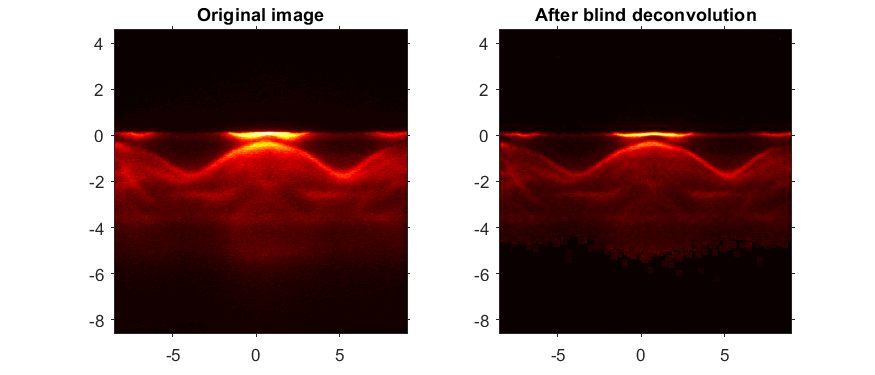

[ProcessedImg,PSF]=deconvblind(Img,psfi,iter,dampar,Weight);
subplot(121);ImData(Angle,Energy,Img);title('Original image')
subplot(122);ImData(Angle,Energy,ProcessedImg);title('After blind deconvolution')
set(gcf,'Position',[0,0,700,300]);

The image has clearly changed. To inspect the exact effects, we can focus on certain features of the data and compare:

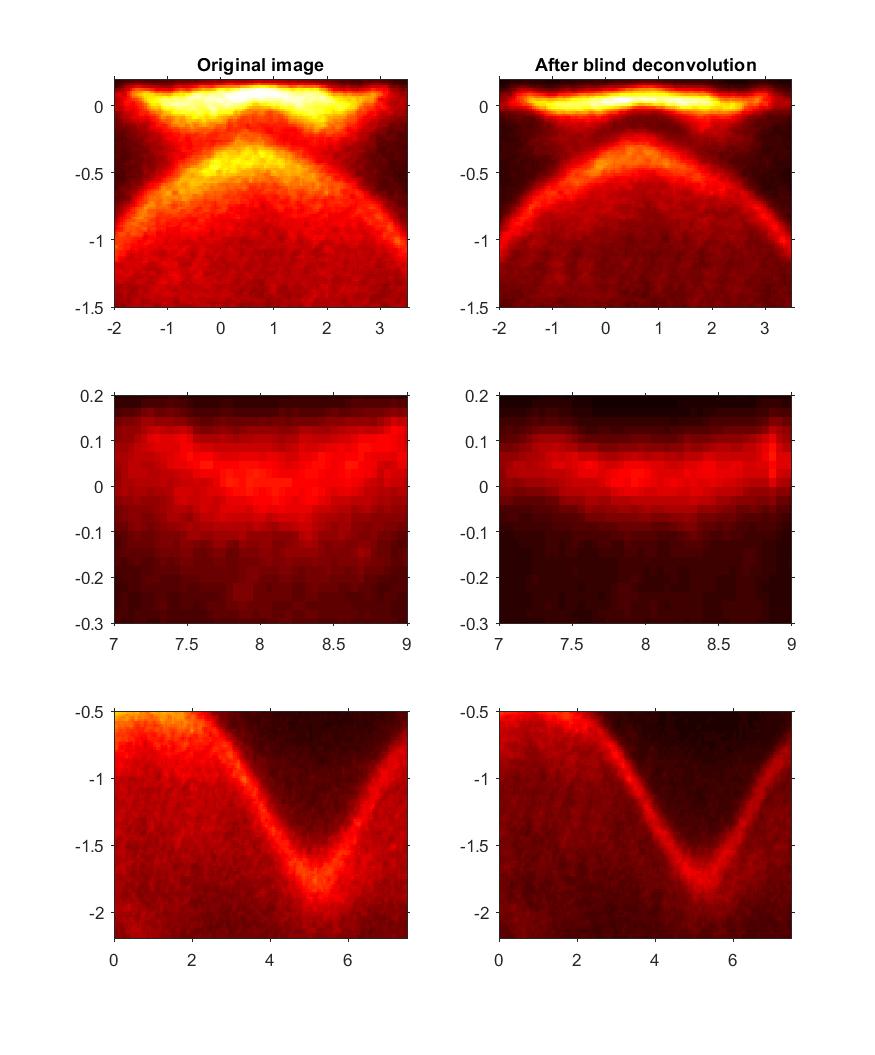

figure;colormap('hot')
sub1=subplot(321);ImData(Angle,Energy,Img);
title('Original image')
sub2=subplot(322);ImData(Angle,Energy,ProcessedImg);
title('After blind deconvolution')
sub3=subplot(323);ImData(Angle,Energy,Img);
sub4=subplot(324);ImData(Angle,Energy,ProcessedImg);
sub5=subplot(325);ImData(Angle,Energy,Img);
sub6=subplot(326);ImData(Angle,Energy,ProcessedImg);
set(gcf,'Position',[0,0,700,900]);
linkaxes([sub1,sub2],'xy')
linkaxes([sub3,sub4],'xy')
linkaxes([sub5,sub6],'xy')
sub1.XLim=[-2,3.5];
sub1.YLim=[-1.5,0.2];
sub3.XLim=[7,9];
sub3.YLim=[-0.3,0.2];
sub6.XLim=[0,7.5];
sub6.YLim=[-2.2,-0.5];

The most prominent features of the data have all obviously gotten sharper as a result of the deconvolution. However, also observe that the upper bands in the central feature shown in the first set of zoomed images may have become more flat as compared to the original image.

It is also possible to examine the reconstructed PSF used to create the final deconvoluted image. It is returned as the second output of `deconvblind`.

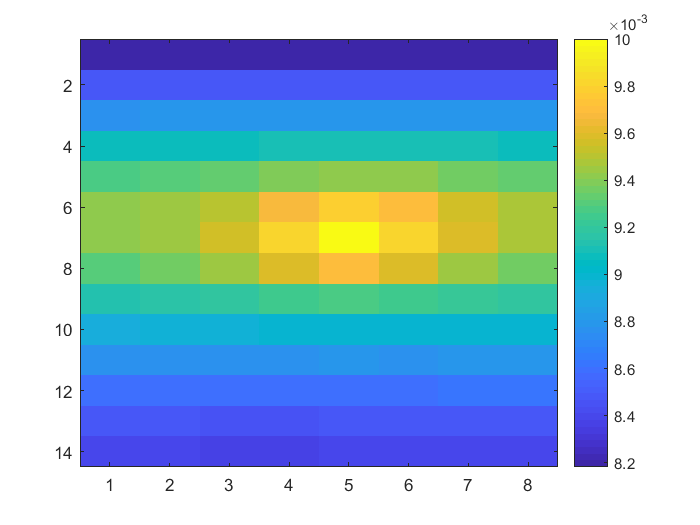

figure;imagesc(flipud(PSF));colorbar

Note that occasionally, an apparently reasonable reconstructed image can also be the result of a nonsensical PSF.

We can use the size of the original image and it's physical proportions to get a handle on the physical size of the PSF recovered in the reconstruction.

dE=14*(max(Energy(:))-min(Energy(:)))/size(Energy,1)

dE = 0.2686

dA=8*(max(Angle(:))-min(Angle(:)))/size(Angle,2)

dA = 0.3581

Giving us the size of the entire PSF in eV and ° respectively.

## Caveats

This is a list of possible issues that might occur in relation to blind deconvolution.

**Non-generality:**

It is important to keep in mind that all the above parameters were chosen based on trial and error experiments performed on a limited set of data. While they seem reasonably general, it is well possible that they might fail completely for a different class of measurements or even different sets of data.

**Instability:**

Over the course of testing the algorithm, it has shown itself to be quite unstable with respect to changes in the parameters, including the number of iterations and the damping.

**Ringing:**

Due to the fast Fourier transform algorithm used for the convolution calculation, choosing a PSF that is too large can introduce "ringing" effects to high intensity features, essentially duplicating them in the reconstructed image which can easily lead to a misidentification of such an error as for example another band. This problem can also be diagnosed if vertical intensity lines appear close and parallel to the right and left borders of the image in areas where there is high intensity at those borders in the original image.

**Local minima:**

As the blind deconvolution algorithm essentially tries to find the minimum of the difference between the original image and the convolution of the reconstructed image with the PSF, it is possible for it to fall into a local minimum. It then returns a nonsensical restored image which often has unrelated pixels in the formerly dark regions become several orders of magnitude more intense than the main features. Alternatively, it might return the original image itself, with a PSF consisting of only one or two non-zero entries. Finally, it may return a resonable looking reconstructed image with an unphysical PSF, again sometimes having only a handful of non-zero entries off at its edges, thus clearly not representative of the actual result of a hypothetical point source imaged by the system.